clc
clear all
Vh = (7.53/24*1000)/960;
Vl = (7.53/24*1000)/920;
Vp = (10.04/24*1000)/900;
Vptot = Vh + Vl + Vp;
fprintf('Volume of plastic entering 1 tank per hour= %.2f m3 \n', Vptot);

Volume of plastic entering 1 tank per hour= 1.13 m3 


rho_bulk = 400;
Vbulk = (25.1/6 * 1000)/400;
fprintf('Approximate volume of max amount of plastic flake in a tank = %.2f m3 \n', Vbulk);

Approximate volume of max amount of plastic flake in a tank = 10.46 m3 


Vactual = (4)*Vptot;
fprintf('Actual volume of plastic in one tank after 4 hours of operation = %.2f m3 \n', Vactual);

Actual volume of plastic in one tank after 4 hours of operation = 4.53 m3 



%Tank size
d = 1.5;
L = 6.5;
Vtank = d^2 * pi/4 * L + (.725^2 * 0.5 * 4/3); %ellipsoidal heads
fprintf('Volume of tank = %.2f m3 \n', Vtank);

Volume of tank = 11.84 m3 


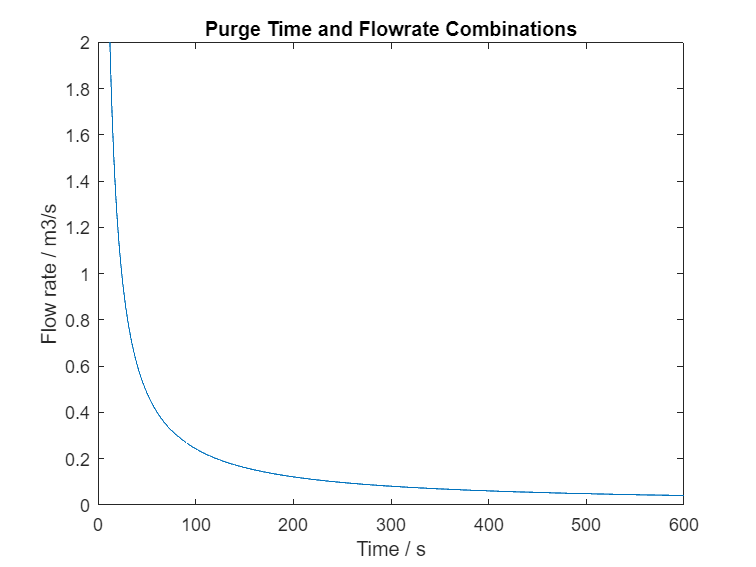


%Dilution purging equation method 1
C0 = 21;
Ci = 0;
Cf = 4;
Q = 0:0.0005:2;
F = 2;

t = (F*(Vtank-Vactual)./Q) .* log((Ci-C0)/(Ci-Cf));

plot(t,Q)
xlabel("Time / s")
ylabel("Flow rate / m3/s")
title("Purge Time and Flowrate Combinations")
xlim([0 600]);
ylim([0 2]);

V_tot = Q(2)*t(2);
fprintf('Volume of nitrogen needed per 4 hour cycle EQ1 = %.2f m3 \n', V_tot);

Volume of nitrogen needed per 4 hour cycle EQ1 = 24.23 m3 


%finding flow rate to purge for 10mins
[time, i] = min(abs(t-600));
fprintf('Flowrate for 10 minute purge = %.4f m3/s \n', Q(i));

Flowrate for 10 minute purge = 0.0405 m3/s 



rho_Ng = 1.25;
rho_Nl = 807;
Mw_N = 28/1000; %kg/mol
Mw_O = 32/1000;
Tgas = 283;
mass_Nin = 101325*(V_tot*3)/(8.314*Tgas) * Mw_N;
fprintf('Daily nitrogen gas requirement per tank using EQ1 = %.2f m3 \n', V_tot*3);

Daily nitrogen gas requirement per tank using EQ1 = 72.69 m3 


fprintf('Daily nitrogen gas requirement per tank using EQ1 = %.2f kg \n', mass_Nin);

Daily nitrogen gas requirement per tank using EQ1 = 87.65 kg 


fprintf('Daily total nitrogen gas requirement using EQ1 = %.2f m3 \n', V_tot*6);

Daily total nitrogen gas requirement using EQ1 = 145.38 m3 



Vliq = V_tot*3*1.544;
fprintf('Daily nitrogen liquid requirement per tank = %.2f L \n', Vliq);

Daily nitrogen liquid requirement per tank = 112.24 L 


fprintf('Daily total nitrogen liquid requirement = %.2f L \n', Vliq*2);

Daily total nitrogen liquid requirement = 224.47 L 



%composition to reactor 4% O2 96% N2
Tinit = 283;
mass_Nreac = 101325*(Vtank - Vptot)*0.96/(8.314*Tgas) * Mw_N * 2;
fprintf(' Mass of Nitrogen to reactor from one tank = %.2f kg/day \n', mass_Nreac);

 Mass of Nitrogen to reactor from one tank = 24.78 kg/day 


mass_Oreac = 101325*(Vtank - Vptot)*0.04/(8.314*Tgas) * Mw_O * 2;
fprintf(' Mass of Oxygen to reactor from one tank = %.2f kg/day \n', mass_Oreac);

 Mass of Oxygen to reactor from one tank = 1.18 kg/day 



mass_Oinitial = 101325*(Vtank - Vptot)*0.21*2/(8.314*Tinit) * Mw_O;
fprintf(' Mass of Oxygen in one tank before purge = %.2f kg \n', mass_Oinitial);

 Mass of Oxygen in one tank before purge = 6.20 kg 


mass_Oout = mass_Oinitial - mass_Oreac;
fprintf(' Mass of Oxygen in outlet of one tank = %.2f kg/day \n', mass_Oout);

 Mass of Oxygen in outlet of one tank = 5.02 kg/day 



mass_Ninitial = 101325*(Vtank - Vptot)*0.79*2/(8.314*Tinit) * Mw_N;
fprintf(' Mass of Nitrogen in one tank before purge = %.2f kg \n', mass_Ninitial);

 Mass of Nitrogen in one tank before purge = 20.39 kg 


mass_Nout = mass_Ninitial + mass_Nin - mass_Nreac;
fprintf(' Mass of Nitrogen in outlet of one tank = %.2f kg/day \n', mass_Nout);

 Mass of Nitrogen in outlet of one tank = 83.26 kg/day 



%tank thickness hoop stress negligible

beta = d/(2*0.5);
K = (2+beta^2)/6;
avgrho = 960*.3 + 920*.3 + 900*.4;
S = 165000000; % maximum allowable stress for SA-285
P = Vactual*avgrho*9.81/(pi*.725^2) + 101325;

tb = P*d*1000*K/(2*S - 0.2*P);
fprintf('Minimum thickness of bottom plate = %.2f mm \n', tb);

Minimum thickness of bottom plate = 0.41 mm 


tc = (P*100*d/2)/(S-0.6*P);
fprintf('Minimum circumferential thickness = %.3f mm \n', tc);

Minimum circumferential thickness = 0.057 mm 


tl = (P*100*d/2)/(2*S+0.4*P);
fprintf('Minimum longitudinal thickness = %.3f mm \n', tl);

Minimum longitudinal thickness = 0.029 mm 



fprintf('Minimum thickness regulations allow = %.1f mm \n', 1.5);

Minimum thickness regulations allow = 1.5 mm 


fprintf('Thickness including corrosion allowance = %.0f mm \n', 1.5+2.5);

Thickness including corrosion allowance = 4 mm 


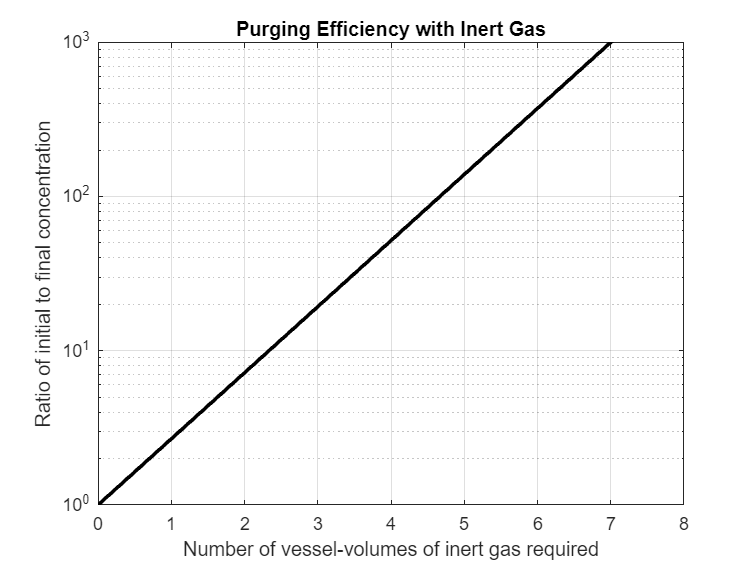

%alternate purging/calculation methods

%dilution purging with method 2
% Define x-axis (Number of vessel-volumes of inert gas required)
x = linspace(0, 8, 100); % Smooth curve with more points

% Define y-axis (Ratio of initial to final concentration)
y = 10.^(x * log10(1000) / 7); % Adjusted scaling to match (7, 850)

% Create the semi-logarithmic plot
figure;
semilogy(x, y, 'k-', 'LineWidth', 2); % Logarithmic Y-axis
hold on;

% Format the plot
grid on;
xlabel('Number of vessel-volumes of inert gas required');
ylabel('Ratio of initial to final concentration');
title('Purging Efficiency with Inert Gas');

% Set axis limits to match the original chart
xlim([0 8]);
ylim([1 1000]);

hold off;


%using dilution purging with graph method 

Conc_ratio = 21/4

Conc_ratio = 5.2500

VV2 = 1.8;
Vn1 = 1.8*(Vtank-Vactual)

Vn1 = 13.1511

%Pressure cycle purging 

VV2 = log(21/4);
Vn2 = VV2*(Vtank-Vactual);

N_req = Vn2*2;
fprintf('Nitrogen gas requirement per cycle EQ2 = %.2f m3 \n', N_req/2);

Nitrogen gas requirement per cycle EQ2 = 12.12 m3 



%Pressure cycle purging
P_range = 0:0.05:5;
n_range = 1:1:5;

now = 100;

for P = P_range
    for n = n_range

        dr = (1./P).^n;
        Cf = 21.*dr;

        if abs(4-Cf) < now && Cf < 4
            Cf_best = Cf;
            best_params = [P,n];
        end

        now = abs(4-Cf);

    end
end

fprintf('P = %.2f, n = %.2f\n', best_params);

P = 3.35, n = 2.00



d_ratio = (1/3.35)^2;
Cf_O = 21*d_ratio % final Oxygen conc

Cf_O = 1.8712


VV =( 3.35-1)*2 %VV = vessel volumes

VV = 4.7000

Vn = VV*(Vtank-Vptot)

Vn = 50.3097

fprintf('Daily total nitrogen gas requirement using cycle purging = %.2f m3 \n', Vn*6);

Daily total nitrogen gas requirement using cycle purging = 301.86 m3 


% Sensitivity Analysis 
tol = 0.9:0.05:1.1;

Vh = (tol*7530/24)/960;
Vl = (tol*7530/24)/920;
Vp = (tol*10400/24)/900;
Vptot = Vh + Vl + Vp;

Vbulk = (tol*25.1/6 * 1000)/400

Vbulk =     9.4125    9.9354   10.4583   10.9813   11.5042


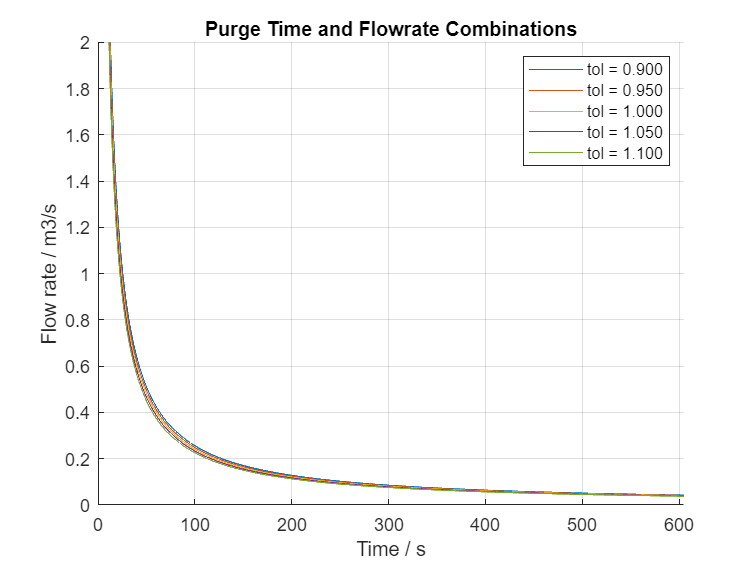

Vtank = 11.84;
Vactual = 4*Vptot;

% Dilution purging equation method 1
C0 = 21;
Ci = 0;
Cf = 4;
Q = 0:0.0005:2;
F = 2;

t_values = zeros(length(Q), length(tol));

figure; 
hold on; 

for i = 1:length(tol)
    t_values(:, i) = (F.*(Vtank-Vactual(i))./Q) .* log((Ci-C0)/(Ci-Cf));
    plot(t_values(:, i), Q, 'DisplayName', sprintf('tol = %.3f', tol(i))); 
end

xlabel("Time / s")
ylabel("Flow rate / m3/s")
title("Purge Time and Flowrate Combinations")
xlim([0 605]);
ylim([0 2]);
legend show; 
grid on;
hold off


% vfull = Vtank-.1;
% tolmax = ((vfull*400))/4183
% Qmax = 0:0.0005:2;
% tmax = (F*(Vtank-vfull)./Qmax) .* log((Ci-C0)/(Ci-Cf));
% 
% volreq = t_values(2,:).*Q(2);

tolnew = 0.9:0.01:1.12;
Vh = (tolnew*7530/24)/960;
Vl = (tolnew*7530/24)/920;
Vp = (tolnew*10400/24)/900;
Vptot = Vh + Vl + Vp;

Vbulk = (tolnew*25.1/6 * 1000)/400;
Vtank = 11.84;
Vactual = 4*Vptot;

t_values = zeros(length(Q), length(tolnew));
for i = 1:length(tolnew)
    t_values(:, i) = (F.*(Vtank-Vactual(i))./Q) .* log((Ci-C0)/(Ci-Cf));
end


vfull = Vtank-.1;
tolmax = ((vfull*400))/4183

tolmax = 1.1226

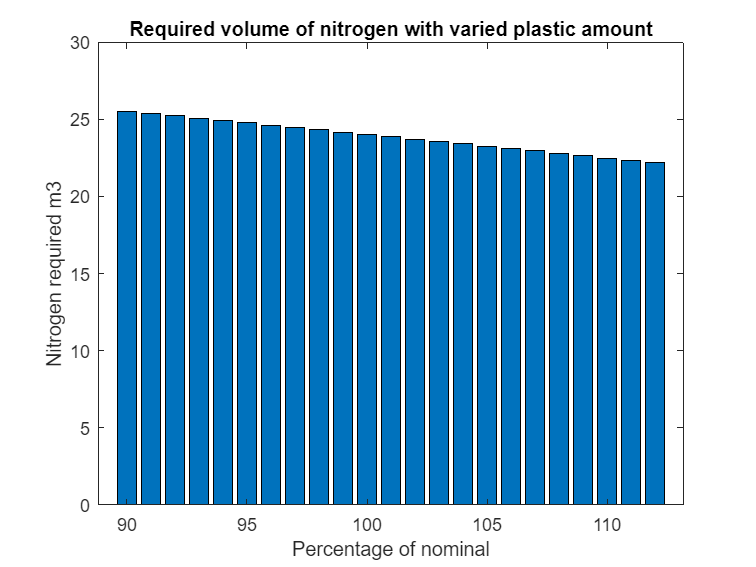

Qmax = 0:0.0005:2;
tmax = (F*(Vtank-vfull)./Qmax) .* log((Ci-C0)/(Ci-Cf));
volreq = t_values(2,:).*Q(2);

bar(tolnew*100, volreq)
xlabel("Percentage of nominal")
ylabel("Nitrogen required m3")
title("Required volume of nitrogen with varied plastic amount")